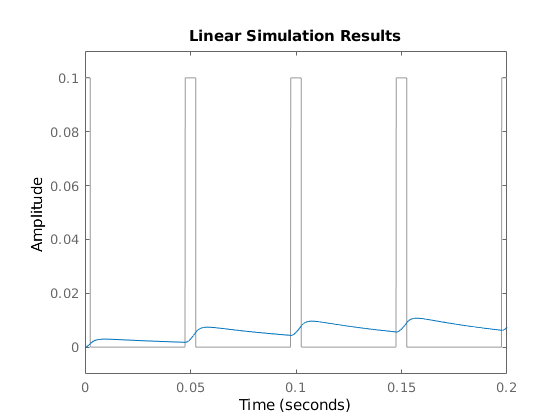

%%% variables %%% 
ks = 200;
b = .5;
kp = 15;
tau = .07;
sys = tf(ks,[b*tau,b+tau*(ks+kp),ks+kp]);


%%% Part c %%%%
Fs = 1e5;
t = 0:1/Fs:.8;

hz = 20;
pulsewidth = .005;
pulseperiods = [0:1/hz:.8];

x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)
axis([0 .2 -0.01 0.11])

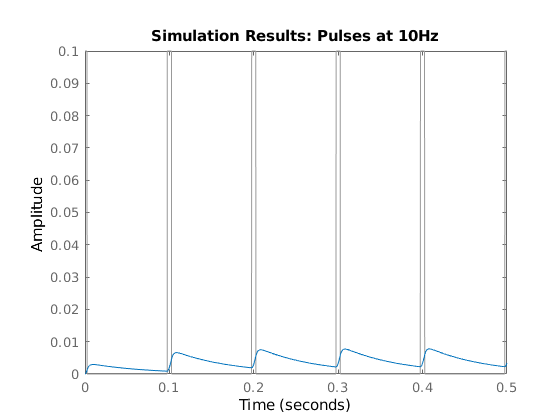



%%% Part d %%%
Fs = 1e5;
t = 0:1/Fs:.5;

hz = 10;
pulsewidth = .005;
pulseperiods = [0:1/hz:.5];
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)
title('Simulation Results: Pulses at 10Hz')

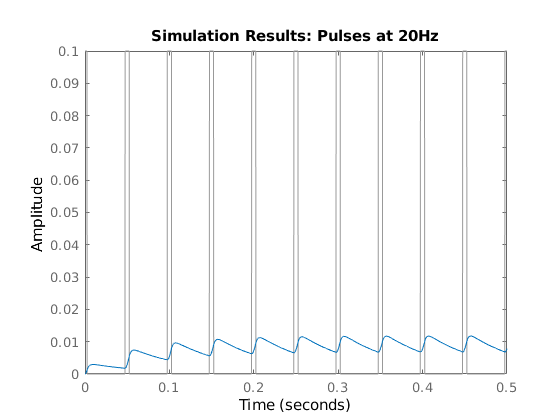



hz = 20;
pulsewidth = .005;
pulseperiods = [0:1/hz:.5];
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)
title('Simulation Results: Pulses at 20Hz')

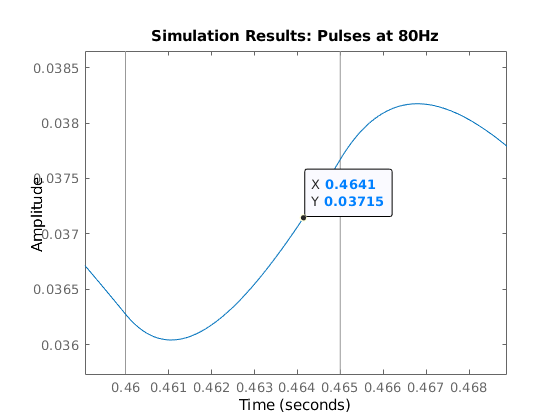


hz = 80;
pulsewidth = .005;
pulseperiods = [0:1/hz:.5];
x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)
title('Simulation Results: Pulses at 80Hz')